# Progetto metodi numerici e modelli matematici, de Cesare

Studio del sistema dinamico autonomo non lineare che descrive in un reattore nucleare ad acqua bollente l'evoluzione nel tempo della potenza P, della temperatura del refrigerante (acqua) $T_r$ e del combustibile (diossido di uranio 235) $T_c$ *(Stabilità di un reattore nucleare:  il metodo di Lyapunov*, Jorio V.M.).

$
\begin{cases}
\frac{dT_c}{dt}&=&-\frac{hS}{V_c\,\rho_cC_c}(T_c-T_r)+\frac{P}{NjV_c\,\rho_cC_c}\\
\frac{dT_r}{dt}&=&\frac{hS}{V_r\,\rho_rC_r}(T_c-T_r) - \frac{v}{\frac{1}{2}L}(T_r-\tau_r) \\
\frac{dP}{dt}&=&\frac{-R_c(T_c-\tau_c)-R_r(T_r-\tau_r)+\delta K_0}{l}\; P
\end{cases}$,

ove i coefficienti $R$ indicano la reattività del materiale, $\delta K_0$ la reattività sotto controllo esterno, $\tau$ le temperature tipiche di funzionamento per reattori BWR, $l$ il tempo in cui avviene la fissione, $h$ il coefficiente di scambio termico, $C$il calore specifico, $\rho$ la densità, $j$ l'equivalente meccanico della caloria e $v$ la velocità del fluido refrigerante.

Si considerano $N$ barre di combustibile, ciascuna di lunghezza $L$, superficie $S$, e volume $V_c$ immerse in una camera cilindrica di volume $V_r$ piena di refrigerante.

Si verifica che a seconda dei dati iniziali inseriti $T_c \left(0\right),{\;T}_r \left(0\right),\;P\left(0\right)$ il reattore si spegne o fonde, provocando nell'ultimo caso un incidente nucleare.

I vincoli del problema fisico impongono che $T_c \left(0\right)\ge \tau {\;}_r \ge T_r \left(0\right)\ge -273,15$.

close all
clear
clc

## Ipotesi di lavoro:

Nella simulazione di una criticità $\delta K_0 =0$, inoltre vengono fissati i seguenti valori (espressi nelle unità di misura SI), immaginando che il modulo in cui avviene la reazione abbia volume di ${80\;cm}^3$, il trasporto di refrigerante (acqua) abbia velocità uniforme sufficientemente bassa (regime laminare) e il combustibile (diossido di uranio UO2) sia immagazzinato in 1 cilindretto lungo 5$\textrm{cm}$ e avente raggio 1$\textrm{cm}$.

$V_r =0\ldotp 01,\;\;v={10}^{-3} ,\;\;L=0,05,\;\;N=1,\;r=0,01$.

Vr = 8e-3;
v = 1e-3;
L = 0.05;
r = 0.01;
N = 1;
S = 2*pi*r^2+2*pi*r*L;
Vc = pi*r^2*L;

I valori di reattività sono stati estrapolati dall'articolo *"Analysis of Reactivity Temperature Coefficient for Light Water Moderated HEU-UAl4 and LEU-UO2 Lattices of MNSR" *(Alhassan E. et al.)

$R_c =-5,{6*10}^{-6} ,\;\;R_r =-0,7*{10}^{-4}$.

Rc = -5.6e-6;
Rr = -0.7e-4;

Alcuni coefficienti noti dalla fisica e dalla chimica:

$500\le h\le 10\;000,\;\;l={10}^{-5} ,\;\;j=4,186,\;\;C_c =0,27,\;C_r =4187,{\;\;\rho }_c =74013,\;\;\rho_r =1000$.

h = 5000;
l = 1e-5;
j = 4.186;
Cc = 0.27;
Cr = 4187;
pc = 74013;
pr = 1000;

Vengono inoltre fissati i valori sulle temperature tipiche di funzionamento per reattori di questo tipo, espresse in gradi centigradi.

tauc0 = 350; taur0 = 30;

Il sistema è nella forma $
\begin{cases}
\frac{dT_c}{dt}&=& -c(T_c-T_r)+dP\\
\frac{dT_r}{dt}&=&e(T_c-T_r) - f(T_r-\tau_r)\\
\frac{dP}{dt}&=& {\Big (} a{\big (}T_c-\tau_c{\big )}+b{\big (}T_r-\tau_r{\big )}{\Big )} \;P
\end{cases}$ con $a,b,c,d,e,f\ge 0$,

a = -Rc/l;
b = -Rr/l;
c = h*S/(Vc*pc*Cc);
d = 1/(N*j*Vc*pc*Cc);
e = h*S/(Vr*pr*Cr);
f = 2*v/L;

il campo vettoriale che ne descrive la dinamica è:

g = @(~,x) [-c*(x(1)-x(2))+d*x(3); e*(x(1)-x(2))-f*(x(2)-taur0); (a*(x(1)-tauc0)+b*(x(2)-taur0))*x(3)];

## Punti di equilibrio:

È possibile calcolare i punti di equilibrio imponendo  $
\begin{cases}
0&=&-\frac{hS}{V_c\,\rho_cC_c}(T_c-T_r)+\frac{P}{NjV_c\,\rho_cC_c}\\
0&=&\frac{hS}{V_r\,\rho_rC_r}(T_c-T_r) - \frac{v}{\frac{1}{2}L}(T_r-\tau_r)\\
0&=&\frac{-R_c(T_c-\tau_c)-R_r(T_r-\tau_r)}{l} \;P
\end{cases}$ e risolvendo il sistema.

Si ricavano due punti di equilibrio: $T_c^s =T_r^s =\tau_r ,\;{\;P}^{\;s} =0\;$ e ${\;T}_c^{\;i} =\frac{-R_c {\tau \;}_c -R_r {\tau \;}_r \left(0\right)+R_r T_r^{\;i} }{-R_c },{\;\;T}_r^{\;i} =\frac{\left(\frac{R_c \;v\;V_r \;\rho_r C_r }{\frac{L}{2}h\;S}+R_r \right)\;\tau_r +R_c {\;\tau }_c }{R_c +\left(\frac{R_c \;v\;V_r \;\rho_r C_r }{\frac{L}{2}h\;S}+R_r \right)},\;{\;P}^{\;i} =N\;j\;h\;S\;\left(T_c^{\;i} -T_r^{\;i} \right)$.

%equilbrio in cui il reattore si spegne
Tcstab = taur0;
Trstab = taur0;
Pstab = 0;
xstab = [Tcstab; Trstab; Pstab];


Escludendo il caso in cui $P=0$ (già trattato)

%equilibrio in cui avviene la fusione del nocciolo
A = [-c c d; e -e-f 0; a b 0 ]; veq = [0; -f*taur0; a*tauc0+b*taur0];
xinc = A\veq;
Tcinc = xinc(1);
Trinc = xinc(2);
Pinc = xinc(3);

## Controlli con vari dati iniziali:

Cambiando le condizioni iniziali si possono effettuare dei confronti sulla stabilità asintotica

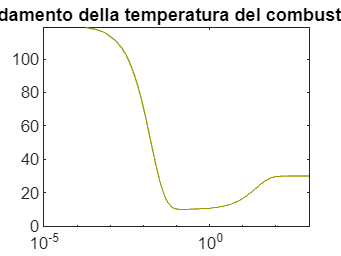

[acct1, accx1] = ode45(g,[0,1e3],[120,10,300]);
figure
semilogx(acct1,accx1(:,1), color = [.6 .6 0])
title('andamento della temperatura del combustibile')

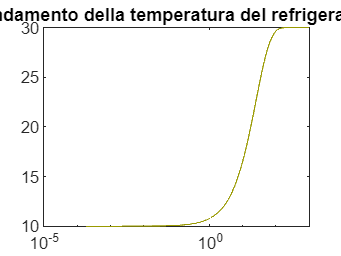

figure
semilogx(acct1,accx1(:,2), color = [.6 .6 0])
title('andamento della temperatura del refrigerante')

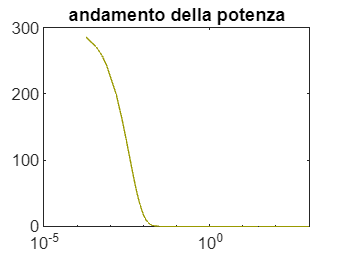

figure
semilogx(acct1,accx1(:,3), color = [.6 .6 0])
title('andamento della potenza')

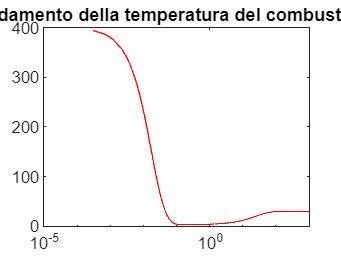


[acct2, accx2] = ode45(g,[0,1e3],[400,3,5000]);
figure
semilogx(acct2,accx2(:,1),'r')
title('andamento della temperatura del combustibile')

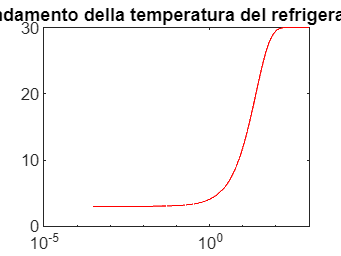

figure
semilogx(acct2,accx2(:,2),'r')
title('andamento della temperatura del refrigerante')

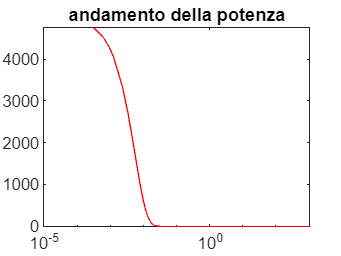

figure
semilogx(acct2,accx2(:,3),'r')
title('andamento della potenza')

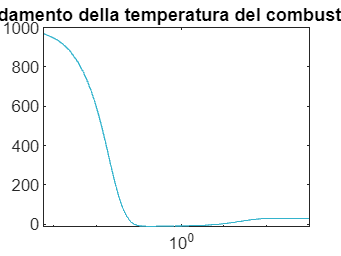


[acct3, accx3] = ode45(g,[0,1e3],[1000,-10,1e4]);
figure
semilogx(acct3,accx3(:,1), color = [.2 .7 .8])
title('andamento della temperatura del combustibile')

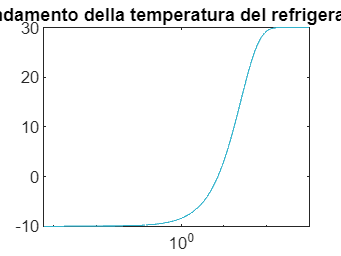

figure
semilogx(acct3,accx3(:,2), color = [.2 .7 .8])
title('andamento della temperatura del refrigerante')

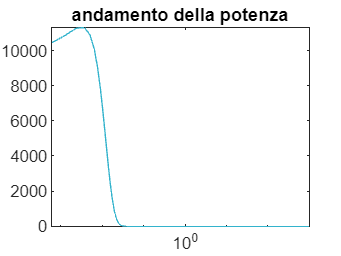

figure
semilogx(acct3,accx3(:,3), color = [.2 .7 .8])
title('andamento della potenza')

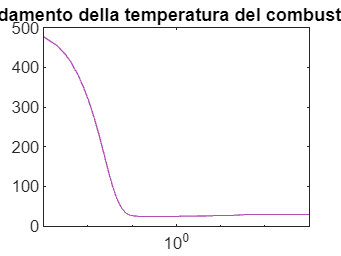


[acct4, accx4] = ode45(g,[0,1e3],[500,25,6e3]);
figure
semilogx(acct4,accx4(:,1), color = [.7 .3 .7])
title('andamento della temperatura del combustibile')

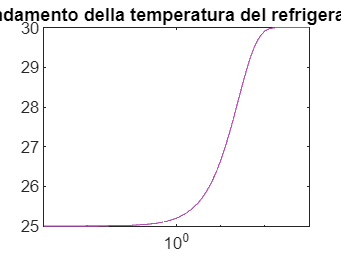

figure
semilogx(acct4,accx4(:,2), color = [.7 .3 .7])
title('andamento della temperatura del refrigerante')

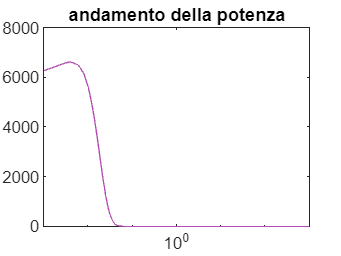

figure
semilogx(acct4,accx4(:,3), color = [.7 .3 .7])
title('andamento della potenza')

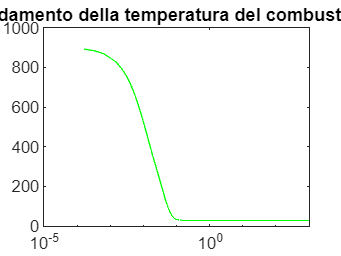


[acct5, accx5] = ode45(g,[0,1e3],[900,30,8e2]);
figure
semilogx(acct5,accx5(:,1), 'g')
title('andamento della temperatura del combustibile')

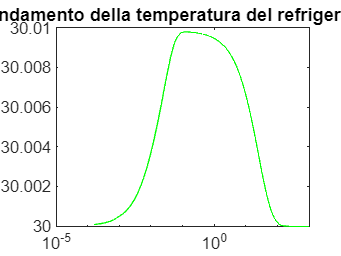

figure
semilogx(acct5,accx5(:,2), 'g')
title('andamento della temperatura del refrigerante')

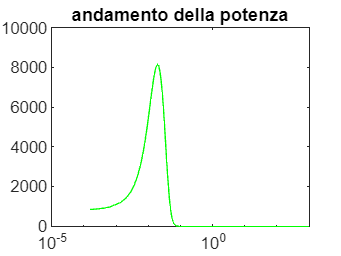

figure
semilogx(acct5,accx5(:,3), 'g')
title('andamento della potenza')


%%%%%
% [acct0, accx0] = ode45(g,[0,1e2],[-273,-30,10]);
% semilogx(acct0,accx0(:,1), 'k')
% title('andamento della temperatura del combustibile')
% figure
% semilogx(acct0,accx0(:,2), 'k')
% title('andamento della temperatura del refrigerante')
% figure
% semilogx(acct0,accx0(:,3), 'k')
% title('andamento della potenza')

## Studio della stabilità dei punti di equilibrio:

Le matrici jacobiane valutate nei due punti di equilibrio individuati sono:

Jgstab = [-c c d; e -e-f 0; a*Pstab b*Pstab (a*(Tcstab-tauc0)+b*(Trstab-taur0))];
Jginc = [-c c d; e -e-f 0; a*Pinc b*Pinc (a*(Tcinc-tauc0)+b*(Trinc-taur0))];

[Vstab, Dstab] = eig(Jgstab);
[Vinc, Dinc] = eig(Jginc);

$\textrm{Jf}\left(x_s \right)$ ha tutti gli autovalori reali e negativi, allora $x_s$ è asintoticamente stabile.

$\textrm{Jf}\left(x_i \right)$ ha autovalori reali, due negativi e uno positivo, allora $x_i$ è instabile, ma esiste una varietà stabile 2-dimensionale su cui le soluzioni convergono a $x_i$.

Per determinare la varietà stabile si definisce il campo vettoriale all'indietro nel tempo

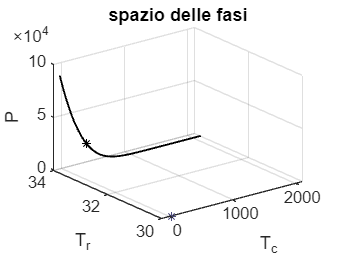

gm = @(~,x) -[-c*(x(1)-x(2))+d*x(3); e*(x(1)-x(2))-f*(x(2)-taur0); (a*(x(1)-tauc0)+b*(x(2)-taur0))*x(3)];

plot3(Tcinc,Trinc,Pinc,'*k', markersize=5)
title('spazio delle fasi')
xlabel('T_c')
ylabel('T_r')
zlabel('P')
grid on
hold on
plot3(Tcstab,Trstab,Pstab,'*', markersize=5, color = [.3 .3 .5])
%profilo 1 della varietà
xVs01 = xinc-1e-3*Vinc(:,1);
[tVs1, xVs1] = Eulero_esp(gm,[0,.165],xVs01,1e-3);
plot3(xVs1(:,1),xVs1(:,2),xVs1(:,3),'k',linewidth=1)

%profilo 2
xVs02 = xinc+1e-3*Vinc(:,1);
[tVs2, xVs2] = Eulero_esp(gm,[0,.14],xVs02,1e-3);
plot3(xVs2(:,1),xVs2(:,2),xVs2(:,3),'k',linewidth=1)

%profilo 3
xVs03 = xinc-1e-3*Vinc(:,3);
[tVs3, xVs3] = Eulero_esp(gm,[0,.316],xVs03,1e-3);
plot3(xVs3(:,1),xVs3(:,2),xVs3(:,3),'k',linewidth=1)

%profilo 4
xVs04 = xinc+1e-3*Vinc(:,3);
[tVs4, xVs4] = Eulero_esp(gm,[0,.32],xVs04,1e-3);
plot3(xVs4(:,1),xVs4(:,2),xVs4(:,3),'k',linewidth=1)


%varietà stabile
% for i = 1:size(xVs1,1)
%     plot3([xVs4(i+155,1); xVs1(i,1)],[xVs4(i+155,2); xVs1(i,2)],[xVs4(i+155,3); xVs1(i,3)])
% end
% for i = 1:size(xVs2,1)
%     plot3([xVs3(i+175,1); xVs2(i,1)],[xVs3(i+175,2); xVs2(i,2)],[xVs3(i+175,3); xVs2(i,3)])
% end

Inserendo nel grafico precedente nello spazio delle fasi le traiettorie delle soluzioni precedentemente calcolate

plot3(accx1(:,1), accx1(:,2), accx1(:,3),'--', color = [.6 .6 0])
plot3(accx2(:,1), accx2(:,2), accx2(:,3),'--r')
plot3(accx3(:,1), accx3(:,2), accx3(:,3),'--', color = [.2 .7 .8])
plot3(accx4(:,1), accx4(:,2), accx4(:,3),'--', color = [.8 .5 .8])
plot3(accx5(:,1), accx5(:,2), accx5(:,3),'--g')

%%%%
% plot3(accx0(:,1), accx0(:,2), accx0(:,3),'--k')

All'indietro nel tempo le soluzioni si allontanano indefinitamente dal punto di equilibrio

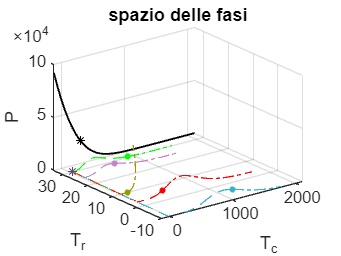

[acct1i, accx1i] = ode45(gm,[0,.022],[120,10,300]);
plot3(120,10,300,'.', markersize=10, color = [.6 .6 0])
plot3(accx1i(:,1), accx1i(:,2), accx1i(:,3),'-.',color = [.6 .6 0])

[acct2i, accx2i] = ode45(gm,[0,.03],[400,3,5000]);
plot3(400,3,5000,'.r', markersize=10)
plot3(accx2i(:,1), accx2i(:,2), accx2i(:,3),'-.r')

[acct3i, accx3i] = ode45(gm,[0,.01],[1000,-10,1e4]);
plot3(1000,-10,1e4,'.', markersize=10, color = [.2 .7 .8])
plot3(accx3i(:,1), accx3i(:,2), accx3i(:,3),'-.', color = [.2 .7 .8])

[acct4i, accx4i] = ode45(gm,[0,.02],[500,25,6e3]);
plot3(500,25,6e3,'.', markersize=10,color = [.8 .5 .8])
plot3(accx4i(:,1), accx4i(:,2), accx4i(:,3),'-.', color = [.8 .5 .8])

[acct5i, accx5i] = ode45(gm,[0,.01],[900,30,8e2]);
plot3(900,30,8e2,'.g', markersize=10)
plot3(accx5i(:,1), accx5i(:,2), accx5i(:,3),'-.g')


%%%%
% [acct0i, accx0i] = ode45(gm,[0,.013],[-273,-30,10]);
% plot3(-273,-30,10,'*k', markersize=5)
% plot3(accx0i(:,1), accx0i(:,2), accx0i(:,3),'-.k')